% =========================================================================
%  Plotting RS-US-RS chunks
%  Author: Yago Lizarribar
% =========================================================================
clear; clc; close all; warning ('off','all');
FILE = ['/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/data/splitter/gsm/lte/s1/E8-932_806-localization.dat'];

% adds subfolder with functions to PATH
p = '.';
addpath(p); 
addpath([p '/ltess']); 
signal = spec_load(FILE);

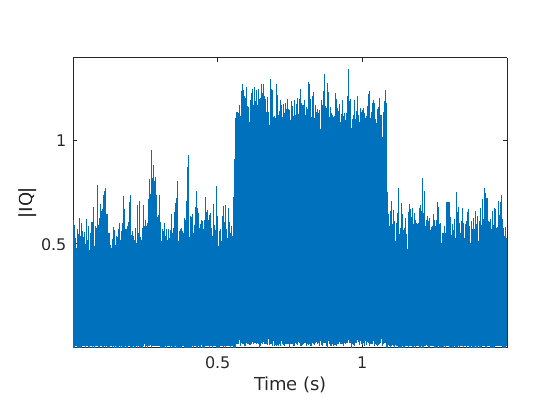

figure(); hold on;
plot(((1:8:length(signal))-1)/2e6, abs(signal(1:8:end)));
xlabel('Time (s)'); ylabel('|IQ|');
set(gca, 'FontSize', 12);
xticks([0.5,1]);
yticks([0.5,1.0]);
pbaspect([1.5,1,1]);
box on;